# **Controlador**

Se comienza por establecer el número de puntos en el trébol y la velocidad lineal esperada para el recorrido.

N = 100; %Número de puntos en el trébol
v = 10; %[cm/s]
pMax = 20*4; %Tomando el cuadro de 20 cm de lado
tRecorrido = pMax/v %[s]

tRecorrido = 8

tsMax = tRecorrido/N %[s]

tsMax = 0.0800

Teniendo en cuenta este tiempo de asentamiento, y que se espera un sobrepico mínimo.

as = 4.5/tsMax

as = 56.2500

Mp = 0.3

Mp = 0.3000

zeta = sqrt((log(Mp)^2)/(pi^2+(log(Mp)^2)))

zeta = 0.3579

Se comienza con el controlador del motor de la base, para el que se espera que no exista sobrepico y se debe tener un tiempo de establecimiento adecuado, es decir, menor al encontrado anteriormente.

%a = 0.7123;
%b = 3.634;
%G1 = tf([a],[1 b 0])

Km1 = 0.161%0.000631%0.161

Km1 = 0.1610

Tau1 = 21.889E-03 %[s]

Tau1 = 0.0219


G1 = tf(Km1,[Tau1 1 0])

G1 =
 
       0.161
  ---------------
  0.02189 s^2 + s
 
Continuous-time transfer function.



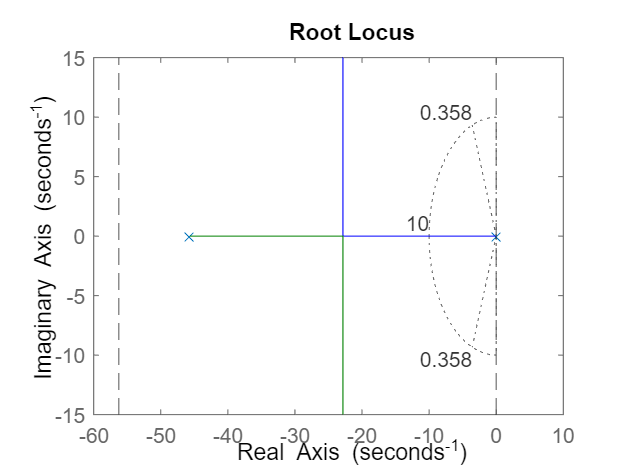

% t = linspace(0,TE1(end),length(TE1))
% y = step(G1,t)
% 
% plot(t,AngleE1)
% hold on
% plot(TE1,y,'r')
% xlabel('Tiempo [ms]')
% ylabel('Posición Angular [°]')
% legend('Datos Experimentales', 'Respuesta al paso FT',Location='northwest')
% title('Identificación planta junta 1')
% 
% 
% figure()
% plot(TE1,abs(y-AngleE1))
% xlabel('Tiempo [ms]')
% ylabel('Error de Posición Angular [°]')
% title('Error en la identificación planta junta 1')
% 
% figure()
% plot(TE1,100*abs(y-AngleE1)./AngleE1)
% xlabel('Tiempo [ms]')
% ylabel('Error porcentual [%]')
% title('Error porcentual en la identificación planta junta 1')
% 
% 
% 
% 
figure()
rlocus(G1)
xline(-as,'--')
xline(0,'--')
sgrid(zeta,10)


kp1 = 815

kp1 = 815


C1 = tf(kp1,1)

C1 =
 
  815
 
Static gain.



Go1 = C1*G1/(1+C1*G1)

Go1 =
 
                 2.872 s^2 + 131.2 s
  -------------------------------------------------
  0.0004791 s^4 + 0.04378 s^3 + 3.872 s^2 + 131.2 s
 
Continuous-time transfer function.



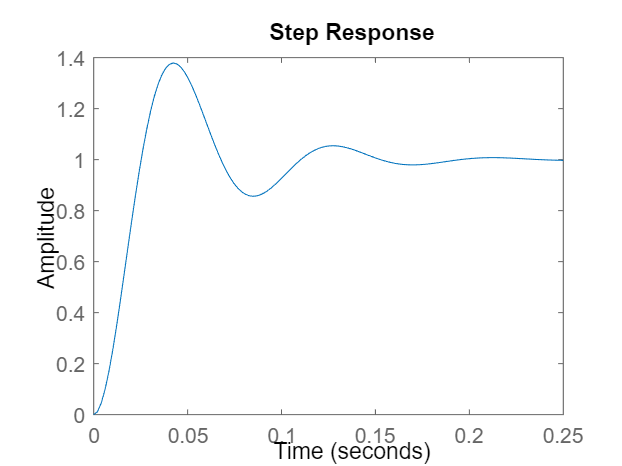

step(Go1)

stepinfo(Go1)

ans = struct with fields:
         RiseTime: 0.0170
    TransientTime: 0.1731
     SettlingTime: 0.1731
      SettlingMin: 0.8563
      SettlingMax: 1.3790
        Overshoot: 37.9049
       Undershoot: 0
             Peak: 1.3790
         PeakTime: 0.0423


Discretizar el controlador

Cz1 = c2d(C1,0.001,'least-squares')

Cz1 =
 
  815
 
Static gain.



a2 = 192.8;
b2 = 25.44;
G2 = tf(a2,[1 b2 0])

G2 =
 
      192.8
  -------------
  s^2 + 25.44 s
 
Continuous-time transfer function.




Km2 = 0.50796%0.001992%0.50796%*0.78431

Km2 = 0.5080

Tau2 = 51.00402E-03 %[s]

Tau2 = 0.0510



G2 = tf(Km2,[Tau2 1 0])

G2 =
 
      0.508
  -------------
  0.051 s^2 + s
 
Continuous-time transfer function.



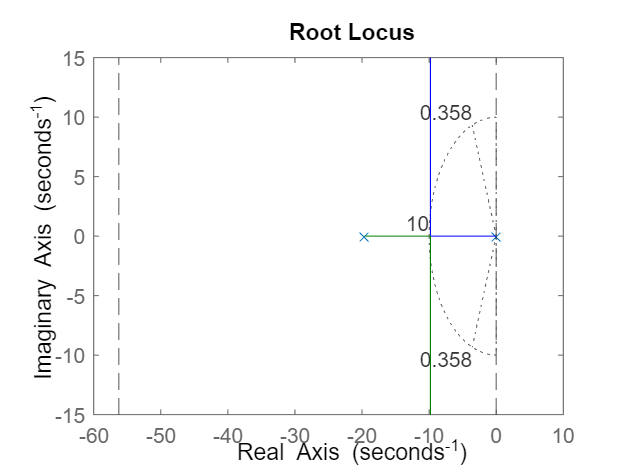


% t = linspace(0,TmsE2(end),length(TmsE2))
% y2 = step(G2,t)
% 
% plot(TmsE2,AngleE2)
% hold on
% plot(t,y2,'r')
% xlabel('Tiempo [ms]')
% xlim([0,180])
% ylabel('Posición Angular [°]')
% legend('Datos Experimentales', 'Respuesta al paso FT',Location='northwest')
% title('Identificación planta junta 2')
% 
% 
% figure()
% plot(TmsE2,abs(y2-AngleE2))
% xlabel('Tiempo [ms]')
% ylabel('Error en Posición Angular [°]')
% xlim([0,180])
% title('Error en la identificación planta junta 2')
% 
% 
% figure()
% plot(TmsE2,100*abs(y2-AngleE2)./AngleE2)
% xlabel('Tiempo [ms]')
% ylabel('Error Porcentual [%]')
% xlim([0,180])
% title('Error porcentual en la identificación planta junta 2')
% 
% 
figure()
rlocus(G2)
xline(-as,'--')
xline(0,'--')
sgrid(zeta,10)


kp2 = 9.65

kp2 = 9.6500


C2 = tf(kp2,1)

C2 =
 
  9.65
 
Static gain.



Go2 = C2*G2/(1+C2*G2)

Go2 =
 
               0.25 s^2 + 4.902 s
  ---------------------------------------------
  0.002601 s^4 + 0.102 s^3 + 1.25 s^2 + 4.902 s
 
Continuous-time transfer function.



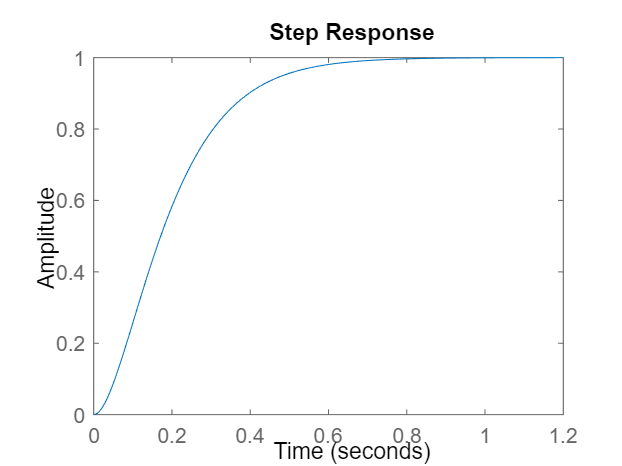

step(Go2)

stepinfo(Go2)

ans = struct with fields:
         RiseTime: 0.3426
    TransientTime: 0.5951
     SettlingTime: 0.5951
      SettlingMin: 0.9020
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 1.2167


Discretizar el controlador

Cz2 = c2d(C2,0.001,'least-squares')

Cz2 =
 
  9.65
 
Static gain.

